Numerical Solution of Boundary-Value Problems

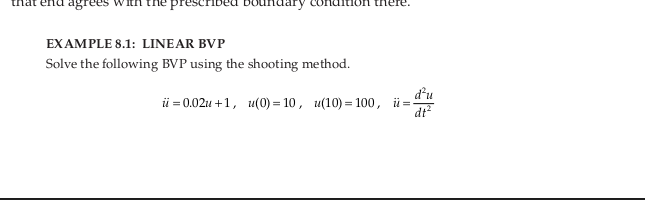

clear;clc;
f = @(t,x)([x(2);0.02*x(1)+1]);
x0_first = [10;10];
t = linspace(0,10,20);
x_first = RK4System(f,t,x0_first);
u_10_first = x_first(1,end)

u_10_first =      2.175208086993421e+02




x0_second = [10;0];
x_second = RK4System(f,t,x0_second);
u_10_second = x_second(1,end)

u_10_second =   80.690974249901657



yi = LagrangeInterp([u_10_first, u_10_second],[10, 0],100)

yi =    1.411170730987996



x0_final = [10;yi];
x_final = RK4System(f,t,x0_final);
x_final(1,end)

ans =      1.000000000000000e+02


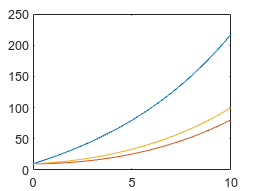



t = linspace(0,10); % 100 points
x_first = RK4System(f,t,x0_first);
u_first = x_first(1,:); % Solution based on the first guess
x_second = RK4System(f,t,x0_second);
u_second = x_second(1,:);   % Solution based on the second guess
x_final = RK4System(f,t,x0_final);
u_final = x_final(1,:);% True solution
plot(t,u_first,t,u_second,t,u_final)

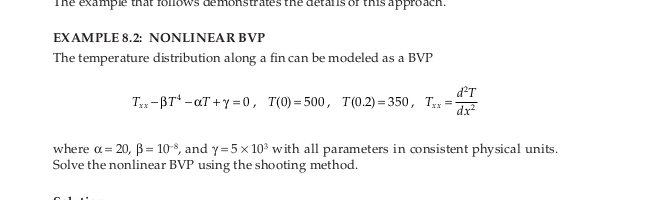

f = @(x,eta)([eta(2);20*eta(1)+1e-8*eta(1)^4-5e3]);
x = linspace(0,0.2);
eta0_first = [500;100];
eta_first = RK4System(f,x,eta0_first);
T_end_first = eta_first(1,end)

T_end_first =      6.462081060998451e+02



eta0_second = [500;-2000];
eta_second = RK4System(f,x,eta0_second);
T_end_second = eta_second(1,end)

T_end_second =      1.570735669008702e+02


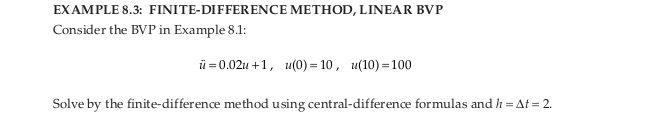

t = 0:2:10;
f = @(t,x)([x(2);0.02*x(1)+1]);
x0 = [10;yi];
% Solutions by the shooting method at interior grid points
u = RK4System(f,t,x0); u(1,[2:end-1])

ans =   15.275972681469007  25.808406096218981  42.445474322042898  66.526940273783097



ue = matlabFunction(dsolve('D2u = 0.02*u+1','u(0)=10, u(10)=100'));

% Exact solutions at interior grid points
ue(t(2:end-1))

ans =   15.276159319865229  25.809318306903833  42.447762366784559  66.531464558529763


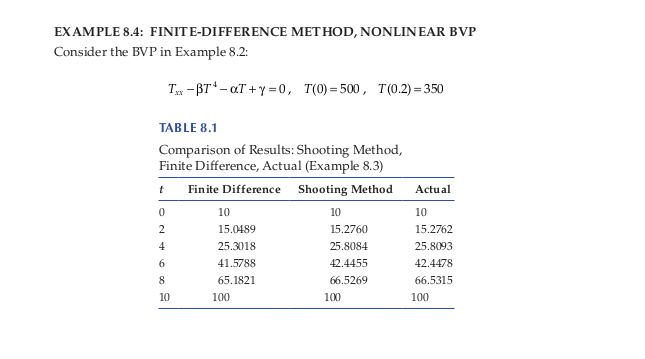

clear;clc;
syms T2 T3 T4 T5
f1 = 508-2.0320*T2-1.6e-11*T2^4+T3; f2 = T2-2.0320*T3-1.6e-11*T3^4+T4+8;
f3 = T3-2.0320*T4-1.6e-11*T4^4+T5+8; f4 = 358+T4-2.0320*T5-1.6e-11*T5^4;
f = [f1;f2;f3;f4];
J = matlabFunction(jacobian(f,[T2,T3,T4,T5]));
F = matlabFunction(f);

tol = 1e-4; kmax = 20; T(1,:) = 400*ones(1,4);

for k = 1:kmax,
    A = J(T(k,1),T(k,2),T(k,3),T(k,4));
    b = -F(T(k,1),T(k,2),T(k,3),T(k,4));
    if abs(b(1)) < tol && abs(b(2)) < tol && abs(b(3)) < tol && abs(b(4)) < tol,
        root = T(k,:);
    return
end

if det(A) == 0,
    break
end

    delT = ThomasMethod(A,b); delT = delT';
    T(k+1,:) = T(k,:) + delT;
    if norm(delT) < tol,
        root = T(k+1,:);
            break
    end
end

T

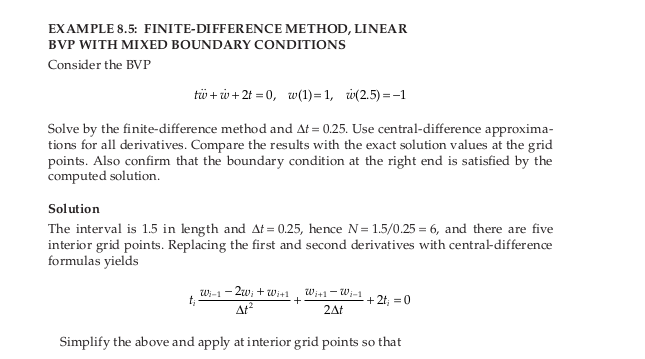

clear;clc;

a = 1; b = 2.5; dt = 0.25;
N = (b-a)/dt; t = a:dt:b;
w1 = 1;% BC at the left end

A = zeros(N-1,N-1); b = zeros(N-1,1); % Pre-allocate
b(1) = -4*t(2)*dt^2-(2*t(2)-dt)*w1;
b(N-1) = -4*t(N)*dt^2+(2/3)*(2*t(N)+dt)*dt;

for i = 1:N-2,
    A(i,i+1) = 2*t(i+1)+dt;
end
for i = 1:N-3,
    A(i+1,i) = 2*t(i+2)-dt;
    b(i+1) = -4*t(i+2)*dt^2;
end
A(N-1,N-2) = (4/3)*(t(N)-dt);
for i = 1:N-2,
    A(i,i) = -4*t(i+1);
end
A(N-1,N-1) = -(4/3)*(t(N)-dt);

w_interior = ThomasMethod(A,b);
w = [w1 w_interior'];
w(N+1) = (1/3)*(-2*dt+4*w(N)-w(N-1));
w

w =    1.000000000000000   1.559895833333333   1.904356060606061   2.080437791375291   2.116375291375291   2.030437791375291   1.835125291375291



% Exact solution
w_ex = matlabFunction(dsolve('t*D2w+Dw+2*t=0','w(1)=1','Dw(2.5)=-1'));

w_e = w_ex(t)

w_e =    1.000000000000000   1.555538317428287   1.895494155405616   2.067309204757835   2.099301927099795   2.009738310811233   1.811090244528081
